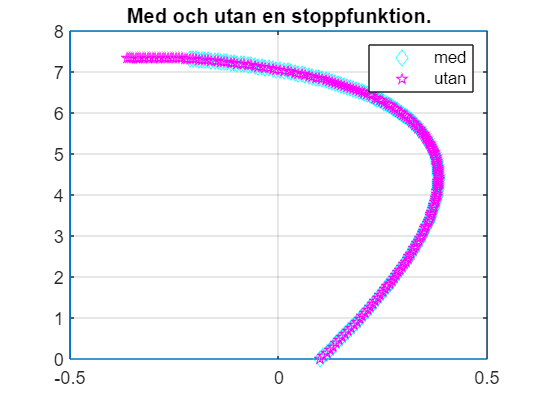

clear
clc
tspan = [0 10];
v0 = 1.6;
n = 200;
y0 = 0.1;
theta = 0.1;

[d1,d2] = drawField();
[y,vy,ty] = yEuler(@yOde,tspan,y0,v0,n,theta);
[x,vx,tx] = xEuler(@xOde,tspan,v0,n,theta);

[x1,vx1,y1,vy1] = calcStop(x,vx,y,vy,n+1);

title('Med och utan en stoppfunktion.');
legend('','med','utan');

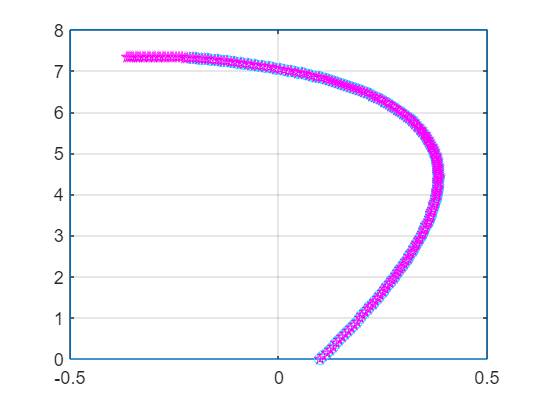

plot(d1,d2,y1,x1,'o c',y,x,'pentagram m');

grid on